close("all"); clear; clc;

vx = 80/3.6;
k = 0;
p = bikeSimToSharp(bigSportsParameters());
sys = sharpMotorcycleStateSpaceFactory(vx,p);

a = [
    0,vx;
    -vx*k^2,0
    ];

A = [
    a,zeros(2),eye(2),zeros(2,4);
    zeros(8,2),sys.a
    ];

B = [
    zeros(2,1);
    sys.b
    ];

C = blkdiag(eye(2),sys.c);

D = 0;

sys = linearSys(A,B,[],C);

params.tFinal = 5;
params.R0 = zonotope(zeros(10,1),zeros(10,1));
params.U = zonotope(interval(-50,50));

options.timeStep = 0.001;
options.zonotopeOrder = 20;
options.taylorTerms = 50;

R = reach(sys,params,options);

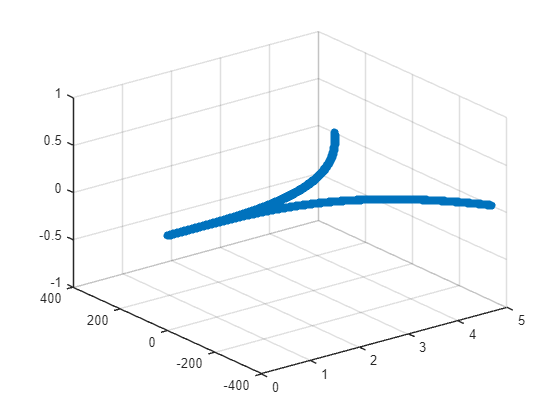

fS = @(R)vertices(reduce(project(R,1:3),"girard",3));
S = cellfun(fS,R.timePoint.set(2:end),"uniform",0);

fC = @(t,S)[
    t.*ones(1,size(S,2));
    S(1,:);
    zeros(1,size(S,2))
    ];

t = R.timePoint.time(2:end);

C = cell2mat(cellfun(fC,t.',S.',"uniform",0));

fig = figure();
axe = axes(fig);
scatter3(axe,C(1,:),C(2,:),C(3,:),"filled");